# ACA _ Project

## Mathematical Model

clear; clc; close all;
% Simulation params( Rigatots 2026)
U=10:0.01:12.7; U_d=18:-0.1:10; eig_vals=zeros(4,length(U));LCO_pitch_max=zeros(size(U));LCO_pitch_max_d=zeros(size(U_d));LCO_pitch_min_d=zeros(size(U_d)) ;LCO_pitch_min=zeros(size(U)); x_0 = [0.00001,0.00001, 0,0.0000111]; tspan = 0:0.0001:10 ;
a_ = -0.6719; b=0.1905; c_a = 0.036; c_h = 27.43; c_la = 6.757; rho = 1.225; x_a= -(0.0998+a_); xe= zeros(4,1);
c_ma =0; mw=4.34;s_p=0.593 ; mt=15.57 ;K_h = 2844.4; K_a0=12.77 ;K_a2=1003 ;  I_a = mw*x_a^2*b^2+0.009039;
 % Control parameter
c_lb = 3.358; c_ly = -1.1566; c_mb = -0.6719; c_my=-0.1005; 
% SOlving ODE
zeta_all=nan(2,length(U)); freq_all=zeta_all; sigma_all=zeta_all;

% for i=1:length(U_d)
%     %options = odeset('RelTol',1e-7,'AbsTol',1e-7);
%     [t,x]=ode45(@(t,x) ODE_model(t,x,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U_d(i),mw,s_p,mt,K_h,I_a,x_a),tspan,x_0);
% 
%     a=x(:,1);  a_dt = x(:,2); h=x(:,3); h_dt=x(:,4);
%     idx = t>=0.8*10; % Only taking the steady LCO parts
%     a_ss = a(idx); % taking the steady state part
%     LCO_pitch_max_d(i)= max(a_ss); LCO_pitch_min_d(i)=min(a_ss);
% end
for i=1:length(U)
    %options = odeset('RelTol',1e-7,'AbsTol',1e-7);
    [t,x]=ode45(@(t,x) ODE_model(t,x,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U(i),mw,s_p,mt,K_h,I_a,x_a),tspan,x_0);
    % fun = @(x)ODE_model(t,x,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U(i),mw,s_p,mt,K_h,I_a,x_a);
    % err = norm(fun(xe));
    % Numerical Jacobian 
    % A= Num_jacob(fun,xe); %disp('Numerical Jaccob:');disp(A);
    % % Eigen analysis
    % [V,D]=eig(A); lambda=eig(A);
    % eig_vals(:,i) = diag(D);
    % idx = find(imag(lambda)>1e-8);
    % % Oscillating modes 
    % lambda_pos = lambda(idx);
    % [~,ord]=sort(abs(imag(lambda_pos))); lambda_pos = lambda_pos(ord);
    % for j=1:min(2,length(lambda_pos))
    %     sig = real(lambda_pos(j));
    %     omg = abs(imag(lambda_pos(j)));
    %     wn = sqrt(sig.^2+omg.^2);
    %     zeta_all(j,i)=-sig/wn;
    %     freq_all(j,i)=omg/(2*pi);
    %     sigma_all(j,i)=sig; 
    % 
    % end
    

    % a=x(:,1);  a_dt = x(:,2); h=x(:,3); h_dt=x(:,4);
    % idx = t>=0.8*10; % Only taking the steady LCO parts
    % a_ss = a(idx); % taking the steady state part
    % LCO_pitch_max(i)= max(a_ss); LCO_pitch_min(i)=min(a_ss);
end



a=x(:,1);  a_dt = x(:,2); h=x(:,3); h_dt=x(:,4);

## Plotting the LCO vel figure

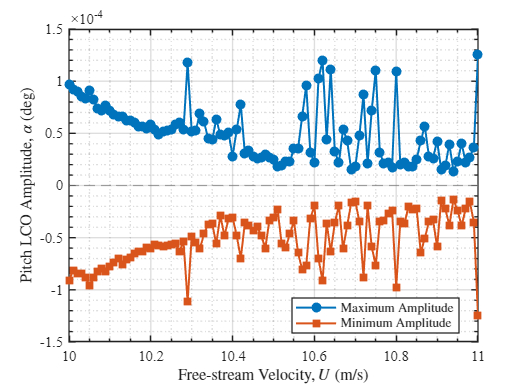

figure('Units', 'inches', 'Position', [1, 1, 5.5, 4.0]);

% Plot pitch LCO bounds with professional marker face colors and line weights
plot(U, 180.*LCO_pitch_max./pi, 'o-', 'LineWidth', 1.5, 'MarkerSize', 6, ...
     'MarkerFaceColor', [0.00, 0.45, 0.74], 'Color', [0.00, 0.45, 0.74]); 
hold on;
plot(U, 180.*LCO_pitch_min./pi, 's-', 'LineWidth', 1.5, 'MarkerSize', 6, ...
     'MarkerFaceColor', [0.85, 0.33, 0.10], 'Color', [0.85, 0.33, 0.10]); 

% Reference line at zero amplitude
yline(0, '--', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1.0);

% Axis labels with LaTeX interpreter
xlabel('Free-stream Velocity, $U$ (m/s)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Pitch LCO Amplitude, $\alpha$ (deg)', 'Interpreter', 'latex', 'FontSize', 12);

% Legend configuration
legend({'Maximum Amplitude', 'Minimum Amplitude'}, ...
       'Interpreter', 'latex', ...
       'Location', 'best', ...
       'FontSize', 10, ...
       'Box', 'on');

% Grid and publication-standard axis aesthetics
grid on;
grid minor;
set(gca, ...
    'Box', 'on', ...
    'TickDir', 'in', ...
    'TickLength', [.015 .015], ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on', ...
    'LineWidth', 1.0, ...
    'FontName', 'Times New Roman', ...
    'FontSize', 11);

hold off;


% figure;
% plot(U_d,LCO_pitch_max_d,'o-','LineWidth',1.8,'MarkerSize',5); hold on;
% plot(U_d,LCO_pitch_min_d,'*-','LineWidth',1.8,'MarkerSize',5); hold off;
% title('Pitch LCO Amplitude Vs Free stream Velocity backward');

## Modal Damping Plot

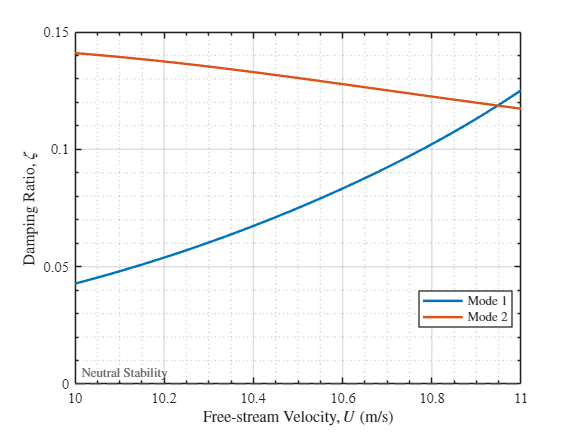

figure('Units', 'inches', 'Position', [1, 1, 6.0, 4.5]);

% Plot modal damping ratios with professional line widths and custom high-contrast colors
plot(U, zeta_all(1,:), 'LineWidth', 1.8, 'Color', [0.00, 0.45, 0.74]); hold on; % Blue
plot(U, zeta_all(2,:), 'LineWidth', 1.8, 'Color', [0.85, 0.33, 0.10]); % Vermilion

% Neutral stability boundary (y = 0)
yline(0, '--', 'Color', [0.4, 0.4, 0.4], 'LineWidth', 1.2, ...
      'Label', 'Neutral Stability', 'LabelHorizontalAlignment', 'left', ...
      'FontSize', 10, 'FontName', 'Times New Roman', 'Interpreter', 'latex');

% Axis labels with LaTeX interpreter
xlabel('Free-stream Velocity, $U$ (m/s)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Damping Ratio, $\zeta$', 'Interpreter', 'latex', 'FontSize', 12);

% Legend configuration (excluding yline if labeled via yline, or keeping clean)
legend({'Mode 1', 'Mode 2'}, ...
       'Interpreter', 'latex', ...
       'Location', 'best', ...
       'FontSize', 10, ...
       'Box', 'on');

% Grid and publication-standard axis aesthetics
grid on;
grid minor;
set(gca, ...
    'Box', 'on', ...
    'TickDir', 'in', ...
    'TickLength', [.015 .015], ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on', ...
    'LineWidth', 1.0, ...
    'FontName', 'Times New Roman', ...
    'FontSize', 11);

hold off;

## Plotting the figure

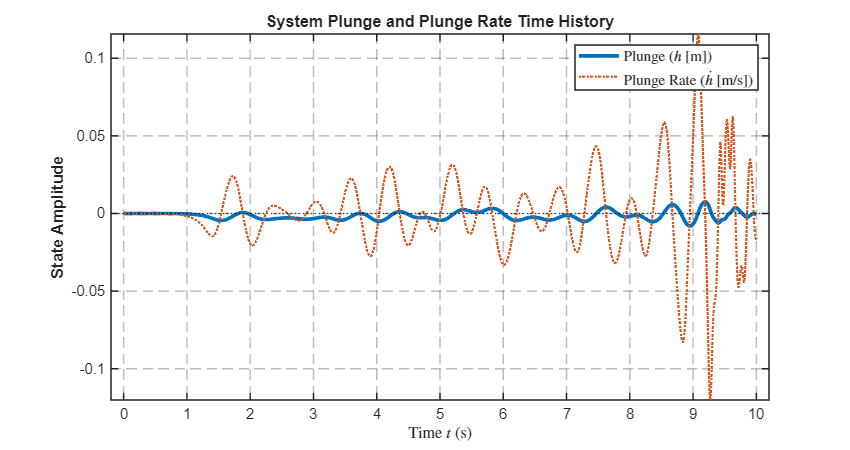



figure('Color', 'w', 'Position', [100, 100, 850, 450]);
hold on; grid on; box on;

% --- Plot Time Histories with Distinct Styling ---
% Mode/State 1: Plunge (h) - Deep Blue, Solid Line
p1 = plot(t, h, '-', ...
    'Color', [0.0000, 0.4470, 0.7410], ...
    'LineWidth', 2.8, ...
    'DisplayName', 'Plunge ($h$ [m])');

% Mode/State 2: Plunge Rate (h_dt) - Warm Red/Orange, Dashed Line
p2 = plot(t, h_dt, ':', ...
    'Color', [0.8500, 0.3250, 0.0980], ...
    'LineWidth', 1.6, ...
    'DisplayName', 'Plunge Rate ($\dot{h}$ [m/s])');

% --- Reference Zero Line ---
yline(0, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Axis Labels & Title ---
title('System Plunge and Plunge Rate Time History', 'FontSize', 13, 'FontWeight', 'bold');
xlabel('Time $t$ (s)', 'Interpreter', 'latex', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('State Amplitude', 'FontSize', 12, 'FontWeight', 'bold');

% --- Axis Limits & Formatting ---
axis tight;
x_padding = 0.02 * (max(t) - min(t));
xlim([min(t) - x_padding, max(t) + x_padding]);

ax = gca;
ax.FontSize = 11;
ax.LineWidth = 1.1;
ax.GridAlpha = 0.3;
ax.GridLineStyle = '--';

% --- Legend Configuration ---
legend([p1, p2], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 11);

hold off;

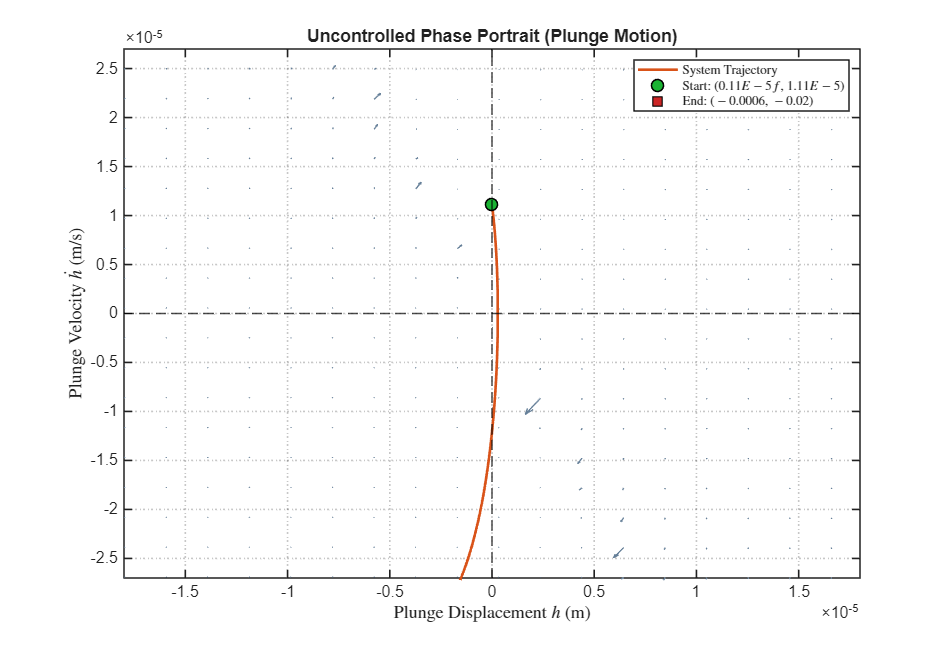

figure('Color', 'w', 'Position', [100, 100, 950, 650]);
hold on; grid on; box on;

N = 60;  U = 12; 
[hx, hy] = meshgrid(linspace(-0.00002, 0.00002, N), linspace(-0.00003, 0.00003, N)); 
[ax, ay] = meshgrid(linspace(-0.25, 0.25, N), linspace(-4, 4, N)); 

h_ddt = zeros(size(hx)); a_ddt = zeros(size(ax)); h_dot = h_ddt; a_dot = a_ddt;

for i = 1:numel(hx)
    state = [hx(i), hy(i), ax(i), ay(i)];
    soln = ODE_model(t, state, rho, a_, c_a, c_h, c_ma, c_la, c_lb, c_ly, c_mb, c_my, b, U, mw, s_p, mt, K_h, I_a, x_a);
    h_dot(i) = soln(3); 
    h_ddt(i) = soln(4); 
    a_ddt(i) = soln(2);  
    a_dot(i) = soln(1);
end

% Compute magnitude for normalization
M = sqrt(h_dot.^2 + a_ddt.^2);
h_dot_norm = h_dot ./ (M + 1e-12); 
h_ddt_norm = h_ddt ./ (M + 1e-12);  

% --- Subsampled Vector Field for Clean Breathing Room ---
skip = 3; 
hx_sub  = hx(1:skip:end, 1:skip:end);
hy_sub  = hy(1:skip:end, 1:skip:end);
hd_sub  = h_dot_norm(1:skip:end, 1:skip:end);
hdd_sub = h_ddt_norm(1:skip:end, 1:skip:end);

% --- Plot Balanced Vector Field (Quiver) ---
q = quiver(hx_sub, hy_sub, hd_sub, hdd_sub, 0.55, ...
    'Color', [0.4, 0.5, 0.6, 0.55], ... 
    'LineWidth', 1.0, ...
    'MaxHeadSize', 0.5);              

% --- Overlay System Phase Trajectory ---
p_traj = plot(h, h_dt, '-', ...
    'Color', [0.8500, 0.3250, 0.0980], ... 
    'LineWidth', 2, ...
    'DisplayName', 'System Trajectory');

% --- Extract Start and End Coordinates ---
h_start = h(1);   h_dot_start = h_dt(1);
h_end   = h(end); h_dot_end   = h_dt(end);

% --- Highlight Starting and Ending Points with Coordinates in Legend ---
p_start = plot(h_start, h_dot_start, 'o', ...
    'MarkerSize', 9, ...
    'MarkerFaceColor', [0.10, 0.70, 0.20], ... 
    'MarkerEdgeColor', 'k', ...
    'LineWidth', 1.2, ...
    'DisplayName', sprintf('Start: ($0.11E-5f$, $1.11E-5$)'));

p_end = plot(h_end, h_dot_end, 's', ...
    'MarkerSize', 9, ...
    'MarkerFaceColor', [0.80, 0.15, 0.15], ... 
    'MarkerEdgeColor', 'k', ...
    'LineWidth', 1.2, ...
    'DisplayName', sprintf('End: ($%.4f$, $%.2f$)', h_end, h_dot_end));

% --- Equilibrium Reference Lines ---
xline(0, 'k--', 'LineWidth', 1.1, 'HandleVisibility', 'off');
yline(0, 'k--', 'LineWidth', 1.1, 'HandleVisibility', 'off');

% --- Labels, Title & Typography ---
title('Uncontrolled Phase Portrait (Plunge Motion)', 'FontSize', 15, 'FontWeight', 'bold');
xlabel('Plunge Displacement $h$ (m)', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Plunge Velocity $\dot{h}$ (m/s)', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');

% --- Axes Formatting ---
axis tight;
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1.2;
ax.GridAlpha = 0.25;
ax.GridLineStyle = ':';

xlim([min(hx(:))*0.9, max(hx(:))*0.9]);
ylim([min(hy(:))*0.9, max(hy(:))*0.9]);

% --- Legend with Dynamic Coordinates ---
legend([p_traj, p_start, p_end], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 10);

hold off;

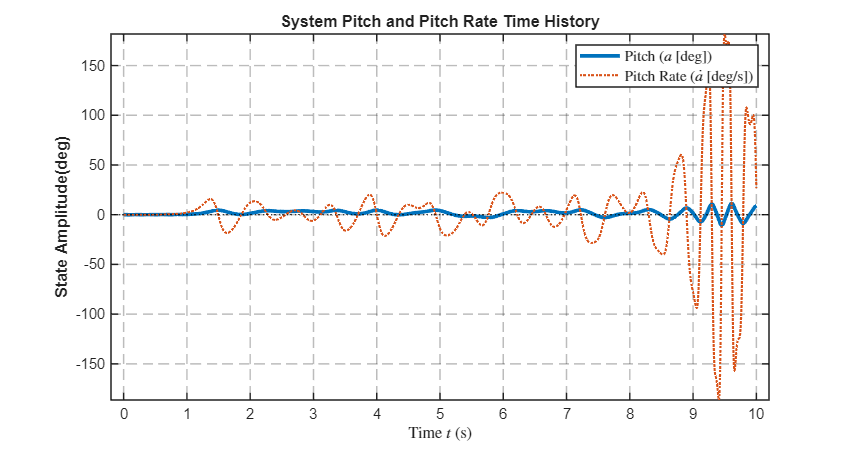

figure('Color', 'w', 'Position', [100, 100, 850, 450]);
hold on; grid on; box on;

% --- Plot Time Histories with Distinct Styling ---
% Mode/State 1: Plunge (h) - Deep Blue, Solid Line
p1 = plot(t, 180.*a./pi, '-', ...
    'Color', [0.0000, 0.4470, 0.7410], ...
    'LineWidth', 2.8, ...
    'DisplayName', 'Pitch ($a$ [deg])');

% Mode/State 2: Plunge Rate (h_dt) - Warm Red/Orange, Dashed Line
p2 = plot(t, 180.*a_dt./pi, ':', ...
    'Color', [0.8500, 0.3250, 0.0980], ...
    'LineWidth', 1.6, ...
    'DisplayName', 'Pitch Rate ($\dot{a}$ [deg/s])');

% --- Reference Zero Line ---
yline(0, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Axis Labels & Title ---
title('System Pitch and Pitch Rate Time History', 'FontSize', 13, 'FontWeight', 'bold');
xlabel('Time $t$ (s)', 'Interpreter', 'latex', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('State Amplitude(deg)', 'FontSize', 12, 'FontWeight', 'bold');

% --- Axis Limits & Formatting ---
axis tight;
x_padding = 0.02 * (max(t) - min(t));
xlim([min(t) - x_padding, max(t) + x_padding]);

ax = gca;
ax.FontSize = 11;
ax.LineWidth = 1.1;
ax.GridAlpha = 0.3;
ax.GridLineStyle = '--';

% --- Legend Configuration ---
legend([p1, p2], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 11);

hold off;

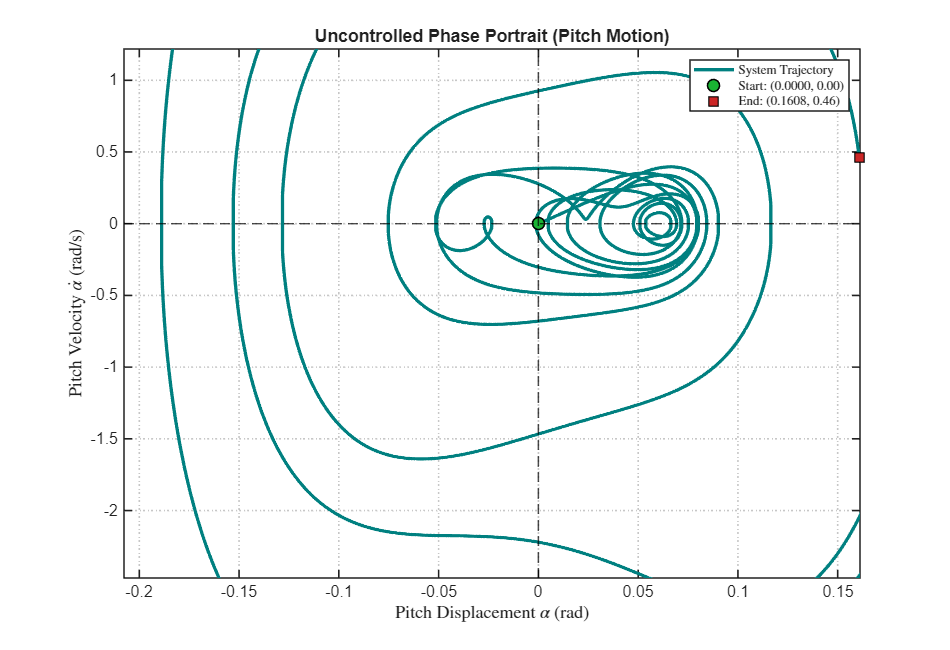


figure(7); clf;
set(gcf, 'Color', 'w', 'Position', [100, 100, 950, 650]);
hold on; grid on; box on;

N = 60;  U = 12.7; 
[hx, hy] = meshgrid(linspace(-0.0002, 0.0002, N), linspace(-0.3, 0.3, N)); 
[ax, ay] = meshgrid(linspace(-0.3, 0.3, N), linspace(-3, 3, N)); 

h_ddt = zeros(size(hx)); a_ddt = zeros(size(ax)); h_dot = h_ddt; a_dot = a_ddt;

for i = 1:numel(ax)
    state = [hx(i), hy(i), ax(i), ay(i)];
    soln = ODE_model(t, state, rho, a_, c_a, c_h, c_ma, c_la, c_lb, c_ly, c_mb, c_my, b, U, mw, s_p, mt, K_h, I_a, x_a);
    h_dot(i) = soln(3); 
    h_ddt(i) = soln(4); 
    a_ddt(i) = soln(2);  % Pitch acceleration (derivative of pitch velocity)
    a_dot(i) = soln(1);  % Pitch velocity (derivative of pitch displacement)
end

% Compute magnitude for normalization on the pitch plane
M_pitch = sqrt(a_dot.^2 + a_ddt.^2);
a_dot_norm = a_dot ./ (M_pitch + 1e-12); 
a_ddt_norm = a_ddt ./ (M_pitch + 1e-12);  

% --- Subsampled Vector Field for Clean Breathing Room ---
skip = 3; 
ax_sub  = ax(1:skip:end, 1:skip:end);
ay_sub  = ay(1:skip:end, 1:skip:end);
ad_sub  = a_dot_norm(1:skip:end, 1:skip:end);
add_sub = a_ddt_norm(1:skip:end, 1:skip:end);

% --- Plot Balanced Vector Field (Quiver) ---
% %q = quiver(ax_sub, ay_sub, ad_sub, add_sub, 0.55, ...
%     'Color', [0.4, 0.5, 0.6, 0.55], ... 
%     'LineWidth', 1.0, ...
%     'MaxHeadSize', 0.5);              

% --- Overlay System Pitch Phase Trajectory ---
p_traj = plot(a, a_dt, '-', ...
    'Color', [0.0000, 0.5000, 0.5000], ...  % Vibrant GREEN
    'LineWidth', 2.5, ...
    'DisplayName', 'System Trajectory');

% --- Extract Start and End Coordinates for Pitch ---
a_start = a(1);   a_dot_start = a_dt(1);
a_end   = a(end); a_dot_end   = a_dt(end);

% --- Highlight Starting and Ending Points with Coordinates in Legend ---
p_start = plot(a_start, a_dot_start, 'o', ...
    'MarkerSize', 9, ...
    'MarkerFaceColor', [0.10, 0.70, 0.20], ... % Vibrant Green for Start
    'MarkerEdgeColor', 'k', ...
    'LineWidth', 1.2, ...
    'DisplayName', sprintf('Start: ($%.4f$, $%.2f$)', a_start, a_dot_start));

p_end = plot(a_end, a_dot_end, 's', ...
    'MarkerSize', 9, ...
    'MarkerFaceColor', [0.80, 0.15, 0.15], ... % Deep Red for End
    'MarkerEdgeColor', 'k', ...
    'LineWidth', 1.2, ...
    'DisplayName', sprintf('End: ($%.4f$, $%.2f$)', a_end, a_dot_end));

% --- Equilibrium Reference Lines ---
xline(0, 'k--', 'LineWidth', 1.1, 'HandleVisibility', 'off');
yline(0, 'k--', 'LineWidth', 1.1, 'HandleVisibility', 'off');

% --- Labels, Title & Typography ---
title('Uncontrolled Phase Portrait (Pitch Motion)', 'FontSize', 15, 'FontWeight', 'bold');
xlabel('Pitch Displacement $\alpha$ (rad)', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Pitch Velocity $\dot{\alpha}$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');

% --- Axes Formatting ---
axis tight;
ax_handle = gca;
ax_handle.FontSize = 12;
ax_handle.LineWidth = 1.2;
ax_handle.GridAlpha = 0.25;
ax_handle.GridLineStyle = ':';

xlim([min(ax(:))*0.9, max(ax(:))*0.9]);
ylim([min(ay(:))*0.9, max(ay(:))*0.9]);

% --- Legend with Dynamic Coordinates ---
legend([p_traj, p_start, p_end], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 10);

hold off;

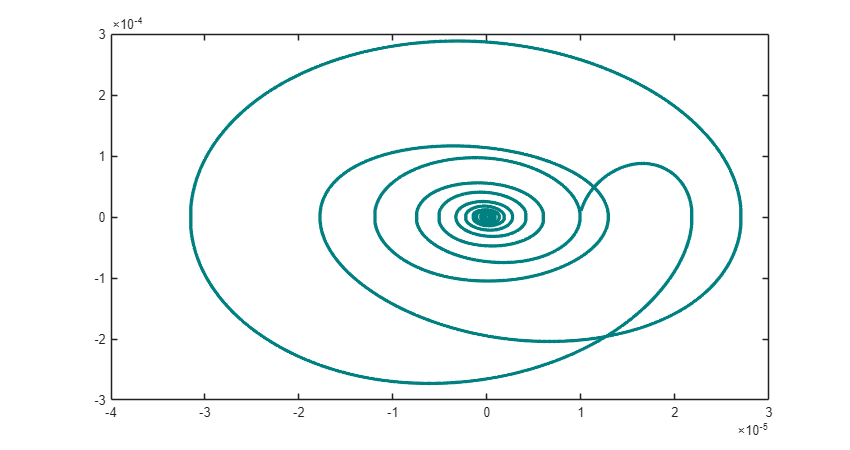


plot(a, a_dt, '-', ...
    'Color', [0.0000, 0.5000, 0.5000], ...  % Vibrant GREEN
    'LineWidth', 2.5, ...
    'DisplayName', 'System Trajectory');

## Eigen Value Analysis and Linearization at Equilibrium Point

% Real part in four plots with velocity

figure('Units', 'inches', 'Position', [1, 1, 9.0, 5.0], 'Color', 'w');

% Define a vibrant, high-contrast color palette and distinct markers for 4 modes
colors = [
    0.00, 0.45, 0.74; % Blue
    0.85, 0.33, 0.10; % Vermilion/Orange
    0.47, 0.67, 0.19; % Green
    0.49, 0.18, 0.56  % Purple
];
markers = {'o', 's', '^', 'd'}; % Circle, Square, Triangle, Diamond

hold on;
for k = 1:4
    plot(U, real(eig_vals(k,:)), ...
         'Marker', markers{k}, ...
         'MarkerSize', 8, ...
         'MarkerFaceColor', colors(k,:), ...
         'Color', colors(k,:), ...
         'LineStyle', 'none', ...
         'LineWidth', 1.5, ...
         'DisplayName', sprintf('Mode %d', k));
end

% Neutral stability boundary (Real part = 0)
yline(0, 'k--', 'LineWidth', 2.0, 'DisplayName', 'Neutral Stability');

% Axis limits and labels with large, projector-friendly fonts & corrected LaTeX
xlim([5 18]);
xlabel('Free-stream Velocity, $U_\infty$ (m/s)', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Real Part of Eigenvalues, $\sigma$', 'Interpreter', 'latex', 'FontSize', 16);
title('Root Locus: Real Eigenvalues vs. Velocity', 'Interpreter', 'latex', 'FontSize', 18, 'FontWeight', 'bold');

% Legend configuration
legend('Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 13, 'Box', 'on');

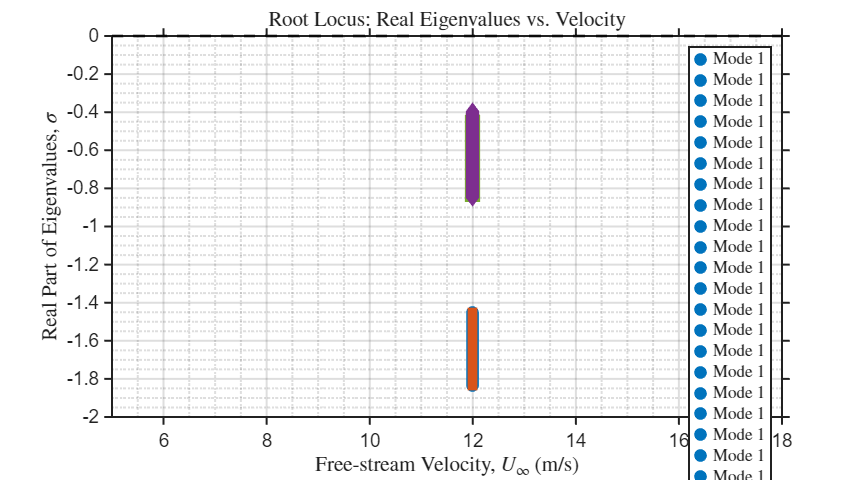


% Presentation-standard grid and axes aesthetics (Sans-serif is best for slides)
grid on;
grid minor;
set(gca, ...
    'Box', 'on', ...
    'TickDir', 'out', ...
    'LineWidth', 1.5, ...
    'FontName', 'Helvetica', ...
    'FontSize', 14);

hold off;


figure('Units', 'inches', 'Position', [1, 1, 9.0, 5.0], 'Color', 'w');

% Define a vibrant, high-contrast color palette and distinct markers for 4 modes
colors = [
    0.00, 0.45, 0.74; % Blue
    0.85, 0.33, 0.10; % Vermilion/Orange
    0.47, 0.67, 0.19; % Green
    0.49, 0.18, 0.56  % Purple
];
markers = {'o', 's', '^', 'd'}; % Circle, Square, Triangle, Diamond

hold on;
for k = 1:4
    plot(U, imag(eig_vals(k,:)), ...
         'Marker', markers{k}, ...
         'MarkerSize', 8, ...
         'MarkerFaceColor', colors(k,:), ...
         'Color', colors(k,:), ...
         'LineStyle', 'none', ...
         'LineWidth', 1.5, ...
         'DisplayName', sprintf('Mode %d', k));
end

% Neutral stability boundary (Real part = 0)
yline(0, 'k--', 'LineWidth', 2.0, 'DisplayName', 'Neutral Stability');

% Axis limits and labels with large, projector-friendly fonts & corrected LaTeX
xlim([5 18]);
xlabel('Free-stream Velocity, $U_\infty$ (m/s)', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Real Part of Eigenvalues, $\sigma$', 'Interpreter', 'latex', 'FontSize', 16);
title('Root Locus: Imag Eigenvalues vs. Velocity', 'Interpreter', 'latex', 'FontSize', 18, 'FontWeight', 'bold');

% Legend configuration
legend('Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 13, 'Box', 'on');

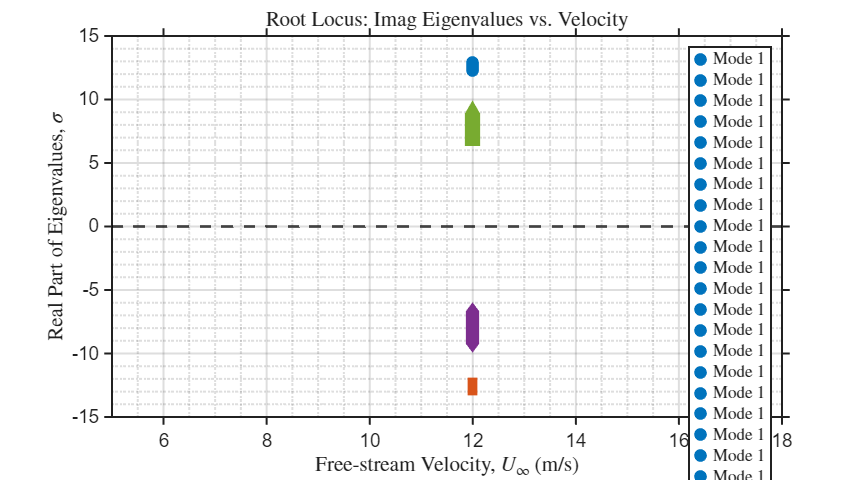


% Presentation-standard grid and axes aesthetics (Sans-serif is best for slides)
grid on;
grid minor;
set(gca, ...
    'Box', 'on', ...
    'TickDir', 'out', ...
    'LineWidth', 1.5, ...
    'FontName', 'Helvetica', ...
    'FontSize', 14);

hold off;

## Eigvalues tracks in complex plane

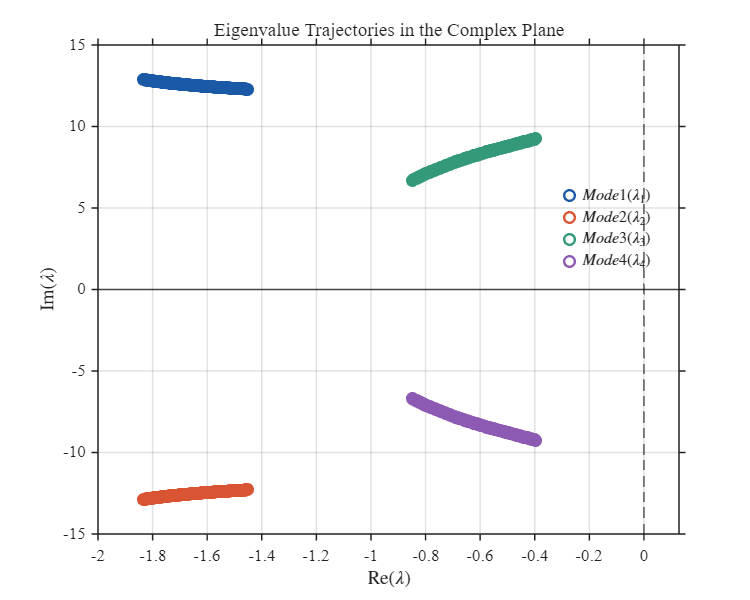


figure('Color','w','Position',[250 150 750 600]);
hold on;

C = [0.10 0.35 0.65;
     0.85 0.33 0.20;
     0.20 0.60 0.48;
     0.55 0.35 0.70];

for k = 1:4
    plot(real(eig_vals(k,:)), imag(eig_vals(k,:)), 'o', ...
        'Color',C(k,:), ...
        'MarkerSize',8, ...
        'LineWidth',1.8, ...
        'DisplayName',sprintf('$Mode %d (\\lambda_%d)$',k,k));
end

% Axes through origin
xline(0,'k--','LineWidth',1.1,'HandleVisibility','off');
yline(0,'k-','LineWidth',0.7,'HandleVisibility','off');

% Labels and title
xlabel('$\mathrm{Re}(\lambda)$','Interpreter','latex','FontSize',16);
ylabel('$\mathrm{Im}(\lambda)$','Interpreter','latex','FontSize',16);
title('Eigenvalue Trajectories in the Complex Plane', ...
      'FontSize',16,'FontWeight','normal');

legend('Interpreter','latex','Location','best', ...
       'Box','off','FontSize',12);

grid on;
set(gca,'FontName','Times New Roman', ...
    'FontSize',13, ...
    'LineWidth',1.1, ...
    'GridAlpha',0.13, ...
    'TickDir','out', ...
    'Box','on');

axis padded;

## Making the observation model

% Making the model
xeq=zeros(4,1); U=12.7;% Origin is our eqlbm
c1=rho*U^2*b^1*s_p;  c2=rho*U^2*b^2*s_p; c_ma_eff = (0.5+xeq(1))*c_la+2*c_ma; c_mb_eff = (0.5+xeq(1))*c_lb+2*c_mb; c_my_eff=(0.5+xeq(1))*c_ly+2*c_my;
c_a1 = c2*mt*c_ma_eff + c1*mw*x_a*b*c_la - mt*K_a0 ;
c_anon1 = -mt*K_a2; c_h1=K_h*mw*x_a*b; 
c_hdot_1= c2*mt*c_ma_eff*(1/U) + c1*mw*x_a*b*c_la*(1/U) + c_h*mw*x_a*b;
c_adot_1 = c2*mt*c_ma_eff*(0.5-xeq(1))*b*(1/U) + c1*mw*x_a*b*c_la*(0.5-xeq(1))*b*(1/U)-c_a*mt;
c_a2 = -c2*mw*x_a*b*c_ma_eff - c1*I_a*c_la + mw*x_a*b*K_a0;
c_anon2= mw*x_a*b*K_a2;   c_h2= -K_h*I_a;
c_adot_2 = -c2*mw*x_a*b*c_ma_eff*(0.5-xeq(1))*b*(1/U) - c1*I_a*c_la*(0.5-xeq(1))*b*(1/U) + c_a*mw*x_a*b;
c_hdot_2 = -c2*mw*x_a*b*c_ma_eff*(1/U) -c1*I_a*c_la*(1/U) -c_h*I_a ;
A_eq = [ 0  1 0 0; c_a1+3*c_anon1*xeq(1)^2  c_adot_1  c_h1  c_hdot_1     ;   0 0 0 1; c_a2+3*c_anon2*xeq(1)  c_adot_2  c_h2  c_hdot_2   ];  

B_eq =[0 0; c2*mt*c_mb_eff+c1*mw*x_a*b*c_lb  c2*mt*c_my_eff+c1*mw*x_a*b*c_ly; 0  0; -c2*mw*x_a*b*c_mb_eff-c1*I_a*c_lb  -c2*mw*x_a*b*c_my_eff-c1*I_a*c_ly ];

C = [1 0 1 0; 1 0 1 0];

OBSV = obsv(A_eq,C);
disp('Rank of the system at the equilibrium point (Origin):'); disp(rank(OBSV));

Rank of the system at the equilibrium point (Origin):
     4



eig(A_eq)

ans =   -0.7429 +10.2760i
  -0.7429 -10.2760i
   5.6581 + 0.0000i
  -5.4368 + 0.0000i


% Chosen OBSV poles 
poles_obs = [-7,-9,-8,-6];
L_cl = place(A_eq',C',poles_obs)'

L_cl =    15.5815   15.5815
  126.1094  126.1094
   -1.2138   -1.2138
  -14.3052  -14.3052


obs_eigs = eig(A_eq-L_cl*C)

obs_eigs =    -9.0000
   -8.0000
   -7.0000
   -6.0000


P_obs=lyap((A_eq-L_cl*C)',eye(4))

P_obs = 1.0e+03 *

    0.0201   -0.0029    0.2125   -0.0185
   -0.0029    0.0029   -0.0377    0.0234
    0.2125   -0.0377    2.7733   -0.2859
   -0.0185    0.0234   -0.2859    0.1930


eig((P_obs+P_obs')/2)

ans = 1.0e+03 *

    0.0000
    0.0037
    0.1641
    2.8214


## For the Controller Model

Q = eye(4); %blkdiag(16,0.0625,1000,25);
[P,~,~]=care(A_eq,B_eq,Q,1);
K__ = B_eq'*P; A_ctrl = A_eq-B_eq*K__;
eig(A_ctrl)

ans =  -86.2553 + 0.0000i
  -1.0862 + 0.0000i
  -1.8196 + 9.1077i
  -1.8196 - 9.1077i


eig((P+P')/2)

ans =     0.0111
    0.9147
    1.1701
   79.1937


## Observer based model Simulation Time

t_meas = linspace(0,10,length(t));
x_meas=zeros(1,2);
x_obs =zeros(6,length(t_meas));
x_obs_o=[0.01;0.01;0;0.0011;0;0];
x_obs(:,1)=x_obs_o;
% for i=1:length(t)
%     %options = odeset('RelTol',1e-7,'AbsTol',1e-7);
%     x_meas = [x(i,1); x(i,3)]; tk=t_meas(i);t_k1=t_meas(i+1);
%     [t_cl,x_cl]=ode45(@(t_cl,x_cl) ODE_model_closed_LQR(t_cl,x_cl,P,x_meas,B_eq,C,L_cl,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a),tspan,x_obs);
% end

## Using RK4

dt=0.01;
for i=1:length(t_meas)-1
       x_cl_obs=x_obs(:,i);
       x_meas=[x(i,1); x(i,3)];
       t=(i-1)*dt;
       RK_1 =ODE_model_closed_LQR(t,x_cl_obs,P,x_meas,B_eq,C,L_cl,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a);
       RK_2 =ODE_model_closed_LQR(t,x_cl_obs+dt*RK_1/2,P,x_meas,B_eq,C,L_cl,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a);
       RK_3 =ODE_model_closed_LQR(t,x_cl_obs+dt*RK_2/2,P,x_meas,B_eq,C,L_cl,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a);
       RK_4 =ODE_model_closed_LQR(t,x_cl_obs+dt*RK_3,P,x_meas,B_eq,C,L_cl,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a);

       x_obs(:,i+1)=x_cl_obs+dt*(RK_1 +RK_2*2+RK_3*2+RK_4)/6;
end



figure;
plot(t_cl,x_obs(1,:)); %ylim([-1 1]);

Unrecognized function or variable 't_cl'.

## Plotting the figures for the closed loop systems

figure;
plot(t_cl,a_cl,t_cl,a_dt_cl);
title('Pitch and Pitch rate Variation LQR System ' );
figure;
plot(a_cl,a_dt_cl); hold on; 
plot(a,a_dt); hold off;
title('Closed Loop Phase portrait of the Pitch Motion ')
figure;
plot(h_cl,h_dt_cl); hold on; 
plot(h,h_dt); hold off;
legend('closed loop','openloop');
title('Closed Loop Phase portrait of the Plunge Motion ')
figure;
plot(t,a);hold on;
plot(t_cl,a_cl); hold off; 
legend('openloop','closed loop');
title('Comparision of pitch angle with Closed Loop System');
figure;
plot(t,h);hold on;
plot(t_cl,h_cl); hold off; 
legend('open loop','closed loop');
title('Comparision of plunge with Closed Loop System');

## Using Control Law in the actual equation

U=12.7; x0_cl=[0.01;0.01;0;0.0011;0;0]; x_0=[0.01;0.01;0;0.0011];
[t_ac,x_ac]=ode45(@(t_ac,x_ac) ODE_model_cl(t_ac,x_ac,P,B_eq,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a),tspan,x0_cl);
    
     %a_ac=x_ac(:,1);  a_dt_ac = x_ac(:,2); h_ac=x_ac(:,3); h_dt_ac=x_ac(:,4);  delta_ac=x_ac(:,5:6);
    a_ac_8=x_ac(:,1);  a_dt_ac_8 = x_ac(:,2); h_ac_8=x_ac(:,3); h_dt_ac_5=x_ac(:,4);  delta_ac_5=x_ac(:,5:6);

% [t,x]=ode45(@(t,x) ODE_model(t,x,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a),tspan,x_0);
% 
%     a=x(:,1);  a_dt = x(:,2); h=x(:,3); h_dt=x(:,4);
% 

## caLC RMSE

%ERR_3 = rmse(a_ac_3,a_ac) % 0.0433
%ERR_5 = rmse(a_ac_5,a_ac)%0.0461
ERR_8 = rmse(a_ac_8,a_ac)%0.0508

ERR_8 = 0.0508

## Plots for this model

figure;
plot(t_ac,h_ac,t_ac,h_dt_ac);
legend('plunge','plunge rate');
title('Comparision of Plunge angle of Closed Loop System');
figure;
plot(t_ac,a_ac,t_ac,a_dt_ac);
title('Pitch and Pitch rate Variation closed loop system ' );
figure('Color','w','Position',[250, 150, 950, 680]);
hold on; grid on; box on;

% --- 1. Open-loop Trajectory & Its Start/End ---
p_open = plot(a, a_dt, '-', ...
    'Color', [0, 0, 0], ...  % Warm Orange/Vermilion
    'LineWidth', 2.2, ...
    'DisplayName', 'Open-loop LCO');

a_open_start = a(1);     ad_open_start = a_dt(1);
a_open_end   = a(end);   ad_open_end   = a_dt(end);

p_open_start = plot(a_open_start, ad_open_start, 'o', ...
    'MarkerSize', 7, 'MarkerFaceColor', [0.85, 0.50, 0.10], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Open Start: (%.3f, %.2f)', a_open_start, ad_open_start));

p_open_end = plot(a_open_end, ad_open_end, '^', ...
    'MarkerSize', 7, 'MarkerFaceColor', [0.85, 0.10, 0.10], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Open End: (%.3f, %.2f)', a_open_end, ad_open_end));


% --- 2. Riccati Closed-loop Trajectory & Its Start/End ---
p_closed = plot(a_ac, a_dt_ac, '--', ...
    'Color', [0.00, 0.45, 0.74], ...  % Deep Electric Blue
    'LineWidth', 3.0, ...              
    'DisplayName', 'Riccati Closed-loop');

a_cl_start = a_ac(1);    ad_cl_start = a_dt_ac(1);
a_cl_end   = a_ac(end);  ad_cl_end   = a_dt_ac(end);

p_cl_start = plot(a_cl_start, ad_cl_start, 'o', ...
    'MarkerSize', 8, 'MarkerFaceColor', [0.10, 0.70, 0.20], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Closed Start: (%.3f, %.2f)', a_cl_start, ad_cl_start));

p_cl_end = plot(a_cl_end, ad_cl_end, 's', ...
    'MarkerSize', 8, 'MarkerFaceColor', [0.00, 0.30, 0.50], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Closed End: (%.3f, %.2f)', a_cl_end, ad_cl_end));


% --- 3. Equilibrium Point ---
p_eq = plot(0, 0, 'kp', ...
    'MarkerFaceColor', 'k', ...
    'MarkerSize', 10, ...
    'DisplayName', 'Equilibrium (0,0)');

% --- Reference Axes Lines ---
xline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');
yline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Pitch Displacement $\alpha$ (rad)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Pitch Velocity $\dot{\alpha}$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Pitch Phase Portrait: Open-Loop vs. Riccati Closed-Loop', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration (Organized) ---
legend([p_open, p_open_start, p_open_end, p_closed, p_cl_start, p_cl_end, p_eq], ...
    'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 9);

% --- Axes Aesthetics ---
axis tight;
set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;
figure('Color','w','Position',[250, 150, 950, 680]);
hold on; grid on; box on;

% --- 1. Open-loop Trajectory (Black) ---
open_color = [0, 0, 0]; % Black

p_open = plot(h, h_dt, '-', ...
    'Color', open_color, ...  
    'LineWidth', 2.2, ...
    'DisplayName', 'Open-loop (Actual System)');

h_open_start = h(1);     hd_open_start = h_dt(1);
h_open_end   = h(end);   hd_open_end   = h_dt(end);

p_open_start = plot(h_open_start, hd_open_start, 'o', ...
    'MarkerSize', 7, 'MarkerFaceColor', [0.6, 0.6, 0.6], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Open Start: (%.4f, %.2f)', h_open_start, hd_open_start));

p_open_end = plot(h_open_end, hd_open_end, '^', ...
    'MarkerSize', 7, 'MarkerFaceColor', open_color, 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Open End: (%.4f, %.2f)', h_open_end, hd_open_end));


% --- 2. Closed-loop Trajectory (Red) ---
closed_color = [0.85, 0.15, 0.15]; % Red

p_closed = plot(h_ac, h_dt_ac, '--', ...
    'Color', closed_color, ...  
    'LineWidth', 1.8, ...              
    'DisplayName', 'Closed-loop (Riccati)');

h_cl_start = h_ac(1);    hd_cl_start = h_dt_ac(1);
h_cl_end   = h_ac(end);  hd_cl_end   = h_dt_ac(end);

p_cl_start = plot(h_cl_start, hd_cl_start, 'o', ...
    'MarkerSize', 8, 'MarkerFaceColor', [1.0, 0.6, 0.6], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Closed Start: (%.4f, %.2f)', h_cl_start, hd_cl_start));

p_cl_end = plot(h_cl_end, hd_cl_end, 's', ...
    'MarkerSize', 8, 'MarkerFaceColor', closed_color, 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Closed End: (%.4f, %.2f)', h_cl_end, hd_cl_end));


% --- 3. Equilibrium Point ---
p_eq = plot(0, 0, 'kp', ...
    'MarkerFaceColor', 'k', ...
    'MarkerSize', 10, ...
    'DisplayName', 'Equilibrium (0,0)');

% --- Reference Axes Lines ---
xline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');
yline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Plunge Displacement $h$ (m)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Plunge Velocity $\dot{h}$ (m/s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Phase Portrait: Open-Loop vs. Closed-Loop (Plunge Motion)', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_open, p_open_start, p_open_end, p_closed, p_cl_start, p_cl_end, p_eq], ...
    'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 9);

% --- Axes Aesthetics ---
axis tight;
set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;
figure('Color', 'w', 'Position', [150, 150, 900, 500]);
hold on; grid on; box on;

% --- 1. Open-Loop Pitch Angle (Black Dash-Dot) ---
p_open = plot(t, a, '-.', ...
    'Color', [0, 0, 0], ...        % Pure Black
    'LineWidth', 2.0, ...
    'DisplayName', 'Open-loop');

% --- 2. Closed-Loop Pitch Angle (Red Solid) ---
p_closed = plot(t_ac, a_ac, '-', ...
    'Color', [0.00, 0.45, 0.74], ... % bLUE
    'LineWidth', 2.6, ...            % Slightly thicker to stand out
    'DisplayName', 'Closed-loop (Riccati)');

% --- Reference Zero Line ---
yline(0, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Time $t$ (s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Pitch Angle $\alpha$ (rad)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Comparison of Pitch Angle: Open-Loop vs. Closed-Loop', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_open, p_closed], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 11);

% --- Axis Limits & Aesthetics ---
axis tight;
x_padding = 0.02 * (max([t(:); t_ac(:)]) - min([t(:); t_ac(:)]));
xlim([min([t(:); t_ac(:)]) - x_padding, max([t(:); t_ac(:)]) + x_padding]);

set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;
figure('Color', 'w', 'Position', [150, 150, 900, 500]);
hold on; grid on; box on;

% --- 1. Open-Loop Plunge Displacement (Black Dash-Dot) ---
p_open = plot(t, h, '-.', ...
    'Color', [0, 0, 0], ...        % Pure Black
    'LineWidth', 2.0, ...
    'DisplayName', 'Open-loop');

% --- 2. Closed-Loop Plunge Displacement (Red Solid) ---
p_closed = plot(t_ac, h_ac, '-', ...
    'Color', [0.85, 0.15, 0.15], ... % Crimson Red
    'LineWidth', 2.6, ...            % Slightly thicker to stand out
    'DisplayName', 'Closed-loop (Riccati)');

% --- Reference Zero Line ---
yline(0, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Time $t$ (s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Plunge Displacement $h$ (m)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Comparison of Plunge Displacement: Open-Loop vs. Closed-Loop', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_open, p_closed], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 11);

% --- Axis Limits & Aesthetics ---
axis tight;
x_padding = 0.02 * (max([t(:); t_ac(:)]) - min([t(:); t_ac(:)]));
xlim([min([t(:); t_ac(:)]) - x_padding, max([t(:); t_ac(:)]) + x_padding]);

set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;

## Plotting the Control states ( Aileron deflection)

% --- Figure Setup for Riccati Control Input ---
figure('Color', 'w', 'Position', [150, 150, 900, 500]);
hold on; grid on; box on;

% Assume delta_ac is [N x 2] containing [Trailing Flap, Leading Flap]
delta_ric = delta_ac; 

% --- 1. Trailing Flap (Solid Crimson Red) ---
p_ric1 = plot(t_ac, delta_ric(:, 1), '-', ...
    'Color', [0.85, 0.15, 0.15], ... 
    'LineWidth', 2.4, ...
    'DisplayName', 'Trailing Flap ($\beta$)');

% --- 2. Leading Flap (Dashed Electric Blue) ---
p_ric2 = plot(t_ac, delta_ric(:, 2), '--', ...
    'Color', [0.00, 0.45, 0.74], ... 
    'LineWidth', 2.2, ...
    'DisplayName', 'Leading Flap ($\gamma$)');

% --- Reference Zero Line ---
yline(0, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Time $t$ (s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Control Deflection $\delta$ (rad)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Riccati Control Input History: Flap Deflections', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_ric1, p_ric2], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 11);

% --- Axis Limits & Aesthetics ---
axis tight;
x_padding = 0.02 * (max(t_ac) - min(t_ac));
xlim([min(t_ac) - x_padding, max(t_ac) + x_padding]);

set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;



if any(isnan(delta_ac(:)))
    disp('Yes') 
else
    disp('NO')
end


## Backstepping Method

x0_bs=[0.01;0.01;0;0.0011;0;0];
[t_bs,x_bs]=ode45(@(t_bs,x_bs) ODE_model_bs(t_bs,x_bs,P,B_eq,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a),tspan,x0_bs);
%a_bs=x_bs(:,1);  a_dt_bs = x_bs(:,2); h_bs=x_bs(:,3); h_dt_bs=x_bs(:,4);  delta_bs=x_bs(:,5:6);
a_bs_8=x_bs(:,1);  a_dt_bs_5 = x_bs(:,2); h_bs_5=x_bs(:,3); h_dt_bs_5=x_bs(:,4);  delta_bs_3=x_bs(:,5:6);

## rmse

%ERR_BS_3=rmse(a_bs_3,a_bs)% 0.0425

%ERR_BS_5=rmse(a_bs_5,a_bs) %0.0513
ERR_BS_8=rmse(a_bs_8,a_bs)

ERR_BS_8 = 0.0413

## plot of RMSE

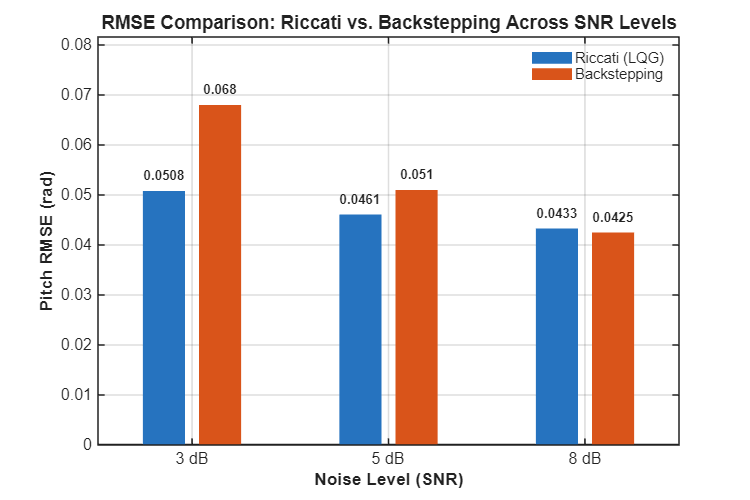

% Noise levels (SNR in dB)
snr_levels = [3, 5, 8];

% Riccati RMSE values for SNR = [3, 5, 8] dB
rmse_riccati = [0.0508, 0.0461, 0.0433];

% Updated Backstepping RMSE values for SNR = [3, 5, 8] dB
rmse_backstepping = [0.0680, 0.0510, 0.0425];

% Combine into matrix for grouped bar plot (rows = SNR groups, cols = controllers)
rmse_data = [rmse_riccati(:), rmse_backstepping(:)];

% Create Figure
figure('Color', 'w', 'Position', [100, 100, 750, 500]);
b = bar(rmse_data, 'grouped', 'BarWidth', 0.75);

% Style bars
b(1).FaceColor = [0.15, 0.45, 0.75]; % Blue for Riccati
b(2).FaceColor = [0.85, 0.33, 0.10]; % Orange-Red for Backstepping
b(1).EdgeColor = 'none';
b(2).EdgeColor = 'none';

% Axes and Labels
set(gca, 'XTickLabel', {'3 dB', '5 dB', '8 dB'}, 'FontSize', 12, 'LineWidth', 1.2);
xlabel('Noise Level (SNR)', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Pitch RMSE (rad)', 'FontSize', 13, 'FontWeight', 'bold');
title('RMSE Comparison: Riccati vs. Backstepping Across SNR Levels', 'FontSize', 14, 'FontWeight', 'bold');
legend({'Riccati (LQG)', 'Backstepping'}, 'Location', 'northeast', 'FontSize', 11, 'Box', 'off');
grid on;
ylim([0, max(rmse_data(:)) * 1.2]);

% Add exact numerical labels on top of each bar
hold on;
for k = 1:numel(b)
    x_pos = b(k).XEndPoints;
    y_pos = b(k).YEndPoints;
    text(x_pos, y_pos + 0.0015, string(round(y_pos, 4)), ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom', ...
        'FontSize', 10, 'FontWeight', 'bold');
end
hold off;

## Plotting of backstepping method

figure('Color', 'w', 'Position', [150, 150, 900, 500]);
hold on; grid on; box on;

% --- 1. Open-Loop Pitch Angle (Black Dash-Dot) ---
p_open = plot(t, a, '-.', ...
    'Color', [0, 0, 0], ...        % Pure Black
    'LineWidth', 2.0, ...
    'DisplayName', 'Open-loop');

% --- 2. Closed-Loop Pitch Angle - Backstepping (Red Solid) ---
p_closed = plot(t_bs, a_bs, '-', ...
    'Color', [0.00, 0.45, 0.74], ... % bLUE
    'LineWidth', 2.6, ...            % Slightly thicker to stand out
    'DisplayName', 'Closed-loop (Backstepping)');

% --- Reference Zero Line ---
yline(0, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Time $t$ (s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Pitch Angle $\alpha$ (rad)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Comparison of Pitch Angle: Open-Loop vs. Backstepping Closed-Loop', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_open, p_closed], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 11);

% --- Axis Limits & Aesthetics ---
axis tight;
x_padding = 0.02 * (max([t(:); t_bs(:)]) - min([t(:); t_bs(:)]));
xlim([min([t(:); t_bs(:)]) - x_padding, max([t(:); t_bs(:)]) + x_padding]);

set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;
figure('Color', 'w', 'Position', [180, 180, 900, 500]);
hold on; grid on; box on;

% --- 1. Open-Loop Plunge Displacement (Black Dash-Dot) ---
p_open = plot(t, h, '-.', ...
    'Color', [0, 0, 0], ...        % Pure Black
    'LineWidth', 2.0, ...
    'DisplayName', 'Open-loop');

% --- 2. Closed-Loop Plunge Displacement - Backstepping (Red Solid) ---
p_closed = plot(t_bs, h_bs, '-', ...
    'Color', [0.85, 0.15, 0.15], ... % Crimson Red
    'LineWidth', 2.6, ...            % Slightly thicker to stand out
    'DisplayName', 'Closed-loop (Backstepping)');

% --- Reference Zero Line ---
yline(0, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Time $t$ (s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Plunge Displacement $h$ (m)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Comparison of Plunge Displacement: Open-Loop vs. Backstepping Closed-Loop', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_open, p_closed], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 11);

% --- Axis Limits & Aesthetics ---
axis tight;
x_padding = 0.02 * (max([t(:); t_bs(:)]) - min([t(:); t_bs(:)]));
xlim([min([t(:); t_bs(:)]) - x_padding, max([t(:); t_bs(:)]) + x_padding]);

set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;
% --- Figure Setup for Backstepping Control Input ---
figure('Color', 'w', 'Position', [180, 180, 900, 500]);
hold on; grid on; box on;

% Assume delta_bs is [N x 2] containing [Trailing Flap, Leading Flap]
delta_bs_input = delta_bs; 

% --- 1. Trailing Flap (Solid Crimson Red) ---
p_bs1 = plot(t_bs, delta_bs_input(:, 1), '-', ...
    'Color', [0.85, 0.15, 0.15], ... 
    'LineWidth', 2.4, ...
    'DisplayName', 'Trailing Flap ($\bets$)');

% --- 2. Leading Flap (Dashed Electric Blue) ---
p_bs2 = plot(t_bs, delta_bs_input(:, 2), '--', ...
    'Color', [0.00, 0.45, 0.74], ... 
    'LineWidth', 2.2, ...
    'DisplayName', 'Leading Flap ($\gamma$)');

% --- Reference Zero Line ---
yline(0, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Time $t$ (s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Control Deflection $\delta$ (rad)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Backstepping Control Input History: Flap Deflections', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_bs1, p_bs2], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 11);

% --- Axis Limits & Aesthetics ---
axis tight;
x_padding = 0.02 * (max(t_bs) - min(t_bs));
xlim([min(t_bs) - x_padding, max(t_bs) + x_padding]);

set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;
figure('Color','w','Position',[250, 150, 950, 680]);
hold on; grid on; box on;

% --- 1. Open-loop Trajectory (Black Dash-Dot) ---
open_color = [0, 0, 0]; % Black

p_open = plot(a, a_dt, '-', ...
    'Color', open_color, ...  
    'LineWidth', 2.2, ...
    'DisplayName', 'Open-loop');

a_open_start = a(1);     ad_open_start = a_dt(1);
a_open_end   = a(end);   ad_open_end   = a_dt(end);

p_open_start = plot(a_open_start, ad_open_start, 'o', ...
    'MarkerSize', 7, 'MarkerFaceColor', [0.6, 0.6, 0.6], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Open Start: (%.3f, %.2f)', a_open_start, ad_open_start));

p_open_end = plot(a_open_end, ad_open_end, '^', ...
    'MarkerSize', 7, 'MarkerFaceColor', open_color, 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Open End: (%.3f, %.2f)', a_open_end, ad_open_end));


% --- 2. Backstepping Closed-loop Trajectory (Red Solid) ---
closed_color = [0.00, 0.45, 0.74]; % Red

p_closed = plot(a_bs, a_dt_bs, ':', ...
    'Color', closed_color, ...  
    'LineWidth', 2.8, ...              
    'DisplayName', 'Closed-loop (Backstepping)');

a_cl_start = a_bs(1);    ad_cl_start = a_dt_bs(1);
a_cl_end   = a_bs(end);  ad_cl_end   = a_dt_bs(end);

p_cl_start = plot(a_cl_start, ad_cl_start, 'o', ...
    'MarkerSize', 8, 'MarkerFaceColor', [1.0, 0.6, 0.6], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Closed Start: (%.3f, %.2f)', a_cl_start, ad_cl_start));

p_cl_end = plot(a_cl_end, ad_cl_end, 's', ...
    'MarkerSize', 8, 'MarkerFaceColor', closed_color, 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Closed End: (%.3f, %.2f)', a_cl_end, ad_cl_end));


% --- 3. Equilibrium Point ---
p_eq = plot(0, 0, 'kp', ...
    'MarkerFaceColor', 'k', ...
    'MarkerSize', 10, ...
    'DisplayName', 'Equilibrium (0,0)');

% --- Reference Axes Lines ---
xline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');
yline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Pitch Displacement $\alpha$ (rad)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Pitch Velocity $\dot{\alpha}$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Phase Portrait: Open-Loop vs. Backstepping (Pitch Motion)', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_open, p_open_start, p_open_end, p_closed, p_cl_start, p_cl_end, p_eq], ...
    'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 9);

% --- Axes Aesthetics ---
axis tight;
set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;
figure('Color','w','Position',[280, 180, 950, 680]);
hold on; grid on; box on;

% --- 1. Open-loop Trajectory (Black Dash-Dot) ---
open_color = [0, 0, 0]; % Black

p_open = plot(h, h_dt, '-', ...
    'Color', open_color, ...  
    'LineWidth', 2.2, ...
    'DisplayName', 'Open-loop');

h_open_start = h(1);     hd_open_start = h_dt(1);
h_open_end   = h(end);   hd_open_end   = h_dt(end);

p_open_start = plot(h_open_start, hd_open_start, 'o', ...
    'MarkerSize', 7, 'MarkerFaceColor', [0.6, 0.6, 0.6], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Open Start: (%.4f, %.2f)', h_open_start, hd_open_start));

p_open_end = plot(h_open_end, hd_open_end, '^', ...
    'MarkerSize', 7, 'MarkerFaceColor', open_color, 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Open End: (%.4f, %.2f)', h_open_end, hd_open_end));


% --- 2. Backstepping Closed-loop Trajectory (Red Solid) ---
closed_color = [0.85, 0.15, 0.15]; % Red

p_closed = plot(h_bs, h_dt_bs, '--', ...
    'Color', closed_color, ...  
    'LineWidth', 2.8, ...              
    'DisplayName', 'Closed-loop (Backstepping)');

h_cl_start = h_bs(1);    hd_cl_start = h_dt_bs(1);
h_cl_end   = h_bs(end);  hd_cl_end   = h_dt_bs(end);

p_cl_start = plot(h_cl_start, hd_cl_start, 'o', ...
    'MarkerSize', 8, 'MarkerFaceColor', [1.0, 0.6, 0.6], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Closed Start: (%.4f, %.2f)', h_cl_start, hd_cl_start));

p_cl_end = plot(h_cl_end, hd_cl_end, 's', ...
    'MarkerSize', 8, 'MarkerFaceColor', closed_color, 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Closed End: (%.4f, %.2f)', h_cl_end, hd_cl_end));


% --- 3. Equilibrium Point ---
p_eq = plot(0, 0, 'kp', ...
    'MarkerFaceColor', 'k', ...
    'MarkerSize', 10, ...
    'DisplayName', 'Equilibrium (0,0)');

% --- Reference Axes Lines ---
xline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');
yline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Plunge Displacement $h$ (m)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Plunge Velocity $\dot{h}$ (m/s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Phase Portrait: Open-Loop vs. Backstepping (Plunge Motion)', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_open, p_open_start, p_open_end, p_closed, p_cl_start, p_cl_end, p_eq], ...
    'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 9);

% --- Axes Aesthetics ---
axis tight;
set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;


## Comparison Plot between backstepping and riccati

figure('Color', 'w', 'Position', [150, 150, 900, 500]);
hold on; grid on; box on;

% --- 1. Riccati Closed-Loop Pitch Angle (Electric Blue) ---
p_ric = plot(t_ac, a_ac, '-', ...
    'Color', [0.00, 0.45, 0.74], ... 
    'LineWidth', 2.2, ...
    'DisplayName', 'Riccati Control');

% --- 2. Backstepping Closed-Loop Pitch Angle (Crimson Red) ---
p_bs = plot(t_bs, a_bs, '--', ...
    'Color', [0.85, 0.15, 0.15], ... 
    'LineWidth', 2.6, ...            
    'DisplayName', 'Backstepping Control');

% --- Reference Zero Line ---
yline(0, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Time $t$ (s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Pitch Angle $\alpha$ (rad)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Controller Comparison: Pitch Angle ($\alpha$) Response', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_ric, p_bs], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 11);

% --- Axis Limits & Aesthetics ---
axis tight;
x_padding = 0.02 * (max([t_ac(:); t_bs(:)]) - min([t_ac(:); t_bs(:)]));
xlim([min([t_ac(:); t_bs(:)]) - x_padding, max([t_ac(:); t_bs(:)]) + x_padding]);

set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;
figure('Color', 'w', 'Position', [180, 180, 900, 500]);
hold on; grid on; box on;

% --- 1. Riccati Closed-Loop Plunge (Electric Blue) ---
p_ric = plot(t_ac, h_ac, '-', ...
    'Color', [0.00, 0.45, 0.74], ... 
    'LineWidth', 2.2, ...
    'DisplayName', 'Riccati Control');

% --- 2. Backstepping Closed-Loop Plunge (Crimson Red) ---
p_bs = plot(t_bs, h_bs, '--', ...
    'Color', [0.85, 0.15, 0.15], ... 
    'LineWidth', 2.6, ...            
    'DisplayName', 'Backstepping Control');

% --- Reference Zero Line ---
yline(0, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Time $t$ (s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Plunge Displacement $h$ (m)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Controller Comparison: Plunge Displacement ($h$) Response', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_ric, p_bs], 'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 11);

% --- Axis Limits & Aesthetics ---
axis tight;
x_padding = 0.02 * (max([t_ac(:); t_bs(:)]) - min([t_ac(:); t_bs(:)]));
xlim([min([t_ac(:); t_bs(:)]) - x_padding, max([t_ac(:); t_bs(:)]) + x_padding]);

set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;

figure('Color','w','Position',[250, 150, 950, 680]);
hold on; grid on; box on;

% --- 1. Backstepping Closed-loop Trajectory (Crimson Red) ---
bs_color = [0.85, 0.15, 0.15]; 
p_bs = plot(a_bs, a_dt_bs, '-', ...
    'Color', bs_color, ...  
    'LineWidth', 2.8, ...              
    'DisplayName', 'Backstepping Control');

a_bs_start = a_bs(1);    ad_bs_start = a_dt_bs(1);
a_bs_end   = a_bs(end);  ad_bs_end   = a_dt_bs(end);

p_bs_start = plot(a_bs_start, ad_bs_start, 'o', ...
    'MarkerSize', 8, 'MarkerFaceColor', [1.0, 0.6, 0.6], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('BS Start: (%.3f, %.2f)', a_bs_start, ad_bs_start));

p_bs_end = plot(a_bs_end, ad_bs_end, 's', ...
    'MarkerSize', 8, 'MarkerFaceColor', bs_color, 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('BS End: (%.3f, %.2f)', a_bs_end, ad_bs_end));


% --- 2. Riccati Closed-loop Trajectory (Electric Blue) ---
ric_color = [0.00, 0.45, 0.74]; 
p_ric = plot(a_ac, a_dt_ac, '--', ...
    'Color', ric_color, ...  
    'LineWidth', 2.4, ...  
    'DisplayName', 'Riccati Control');

a_ric_start = a_ac(1);   ad_ric_start = a_dt_ac(1);
a_ric_end   = a_ac(end); ad_ric_end   = a_dt_ac(end);

p_ric_start = plot(a_ric_start, ad_ric_start, 'o', ...
    'MarkerSize', 7, 'MarkerFaceColor', [0.5, 0.8, 1.0], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Riccati Start: (%.3f, %.2f)', a_ric_start, ad_ric_start));

p_ric_end = plot(a_ric_end, ad_ric_end, '^', ...
    'MarkerSize', 7, 'MarkerFaceColor', ric_color, 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Riccati End: (%.3f, %.2f)', a_ric_end, ad_ric_end));


% --- 3. Equilibrium Point ---
p_eq = plot(0, 0, 'kp', ...
    'MarkerFaceColor', 'k', ...
    'MarkerSize', 10, ...
    'DisplayName', 'Equilibrium (0,0)');

% --- Reference Axes Lines ---
xline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');
yline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Pitch Displacement $\alpha$ (rad)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Pitch Velocity $\dot{\alpha}$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Phase Portrait Comparison: Backstepping vs. Riccati (Pitch)', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_bs, p_bs_start, p_bs_end, p_ric, p_ric_start, p_ric_end, p_eq], ...
    'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 9);

% --- Axes Aesthetics ---
axis tight;
set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;
figure('Color','w','Position',[280, 180, 950, 680]);
hold on; grid on; box on;

% --- 1. Backstepping Closed-loop Trajectory (Crimson Red) ---
bs_color = [0.85, 0.15, 0.15]; 
p_bs = plot(h_bs, h_dt_bs, '-', ...
    'Color', bs_color, ...  
    'LineWidth', 2.8, ...              
    'DisplayName', 'Backstepping Control');

h_bs_start = h_bs(1);    hd_bs_start = h_dt_bs(1);
h_bs_end   = h_bs(end);  hd_bs_end   = h_dt_bs(end);

p_bs_start = plot(h_bs_start, hd_bs_start, 'o', ...
    'MarkerSize', 8, 'MarkerFaceColor', [1.0, 0.6, 0.6], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('BS Start: (%.4f, %.2f)', h_bs_start, hd_bs_start));

p_bs_end = plot(h_bs_end, hd_bs_end, 's', ...
    'MarkerSize', 8, 'MarkerFaceColor', bs_color, 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('BS End: (%.4f, %.2f)', h_bs_end, hd_bs_end));


% --- 2. Riccati Closed-loop Trajectory (Electric Blue) ---
ric_color = [0.00, 0.45, 0.74]; 
p_ric = plot(h_ac, h_dt_ac, '--', ...
    'Color', ric_color, ...  
    'LineWidth', 2.4, ...  
    'DisplayName', 'Riccati Control');

h_ric_start = h_ac(1);   hd_ric_start = h_dt_ac(1);
h_ric_end   = h_ac(end); hd_ric_end   = h_dt_ac(end);

p_ric_start = plot(h_ric_start, hd_ric_start, 'o', ...
    'MarkerSize', 7, 'MarkerFaceColor', [0.5, 0.8, 1.0], 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Riccati Start: (%.4f, %.2f)', h_ric_start, hd_ric_start));

p_ric_end = plot(h_ric_end, hd_ric_end, '^', ...
    'MarkerSize', 7, 'MarkerFaceColor', ric_color, 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Riccati End: (%.4f, %.2f)', h_ric_end, hd_ric_end));


% --- 3. Equilibrium Point ---
p_eq = plot(0, 0, 'kp', ...
    'MarkerFaceColor', 'k', ...
    'MarkerSize', 10, ...
    'DisplayName', 'Equilibrium (0,0)');

% --- Reference Axes Lines ---
xline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');
yline(0, 'k--', 'LineWidth', 1.0, 'HandleVisibility', 'off');

% --- Formatting & Typography ---
xlabel('Plunge Displacement $h$ (m)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Plunge Velocity $\dot{h}$ (m/s)', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');

title('Phase Portrait Comparison: Backstepping vs. Riccati (Plunge)', ...
    'FontSize', 15, 'FontWeight', 'bold');

% --- Legend Configuration ---
legend([p_bs, p_bs_start, p_bs_end, p_ric, p_ric_start, p_ric_end, p_eq], ...
    'Location', 'northeast', 'Interpreter', 'latex', 'FontSize', 9);

% --- Axes Aesthetics ---
axis tight;
set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'GridAlpha', 0.25, ...
    'MinorGridAlpha', 0.1, ...
    'GridLineStyle', ':');

grid minor;
hold off;


## Helper Function


% Assume x1 = alpha(pitch) ,x2= pitch rate; x3=plunge(h); x4=plunge rate
function dx_dt = ODE_model(t,x,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a)
    beta=0;y=0;
    % extracting pitch and plunge motion 
    a=x(1);  a_dt = x(2); h=x(3); h_dt=x(4);
    K_a = 12.77+1000.3*a^2;
    c_ma_eff = (0.5+a)*c_la+2*c_ma; c_mb_eff = (0.5+a)*c_lb+2*c_mb; c_my_eff=(0.5+a)*c_ly+2*c_my;

    L=rho*U^2*b*(c_la*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_lb*s_p*beta + c_ly*s_p*y);
    M= rho*U^2*b^2*(c_ma_eff*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_mb_eff*s_p*beta + c_my_eff*s_p*y);
    F = [M;-L];
    M_ode = [I_a , mw*x_a*b; mw*x_a*b , mt ];
    C_ode = [c_a  0;  0  c_h];
    K_ode = [K_a 0; 0 K_h];

    x_dt = [a_dt;h_dt];
    x_=[a;h];
    acc = M_ode\(F-C_ode*x_dt - K_ode*x_);
    dx_dt=zeros(4,1);
    dx_dt(1)=a_dt;
    dx_dt(2)=acc(1);
    dx_dt(3)=h_dt;
    dx_dt(4)=acc(2);

end


%% Function with the closed loop model u=-B'*P*e
function dx_dt_LQR = ODE_model_closed_LQR(t,x_hat,P,x_meas,B_eq,C,L_cl,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a)
    %r=1; % some adjustment coefficient
    % extracting pitch and plunge motion from the measurement
    % [~,idx] = min(abs(t_meas-t)); % logic to find the idx
    % x_meas_=x_meas(idx,:); 
    %a=interp1(t_meas,x_meas(:,1),t,'linear');    h=interp1(t_meas,x_meas(:,3),t,'linear'); 
    y_measured = x_meas;
     state = x_hat(1:4);
    H=(P*state);
    if t > 5
        u=-(transpose(B_eq)*H);
    else 
        u=zeros(2,1);
    end
     beta =max(-0.25,min(0.25 ,u(1)));
     y = max(-0.25,min(0.25,u(2)));
    
    a=x_hat(1);  a_dt = x_hat(2); h=x_hat(3); h_dt=x_hat(4);
    K_a = 12.77+1000.3*a^2;
    c_ma_eff = (0.5+a)*c_la+2*c_ma; c_mb_eff = (0.5+a)*c_lb+2*c_mb; c_my_eff=(0.5+a)*c_ly+2*c_my;

    L=rho*U^2*b*(c_la*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_lb*s_p*beta + c_ly*s_p*y);
    M= rho*U^2*b^2*(c_ma_eff*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_mb_eff*s_p*beta + c_my_eff*s_p*y);
    F = [M;-L];
    M_ode = [I_a , mw*x_a*b; mw*x_a*b , mt ];
    C_ode = [c_a  0;  0  c_h];
    K_ode = [K_a 0; 0 K_h];

    x_dt = [a_dt;h_dt];
    x_=[a;h];
    acc = M_ode\(F-C_ode*x_dt - K_ode*x_);
    x_new = [a_dt;acc(1);h;acc(2)];
    dx_dt_LQR = zeros(6,1);
    dx_dt_LQR(1:4,:) = x_new + L_cl*(y_measured-C*state);
    dx_dt_LQR(5:6,:) = [beta,y];
end


% Function for the obsv model 
function [dx_dt_cl] = ODE_model_cl(t,x,P,B_eq,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a)
    r=1; % some adjustment coefficient
    % extracting pitch and plunge motion 
    SNR = 8;
    signal_power = mean(x.^2);
    noise_power = signal_power / (10^(SNR/10));

    noise = sqrt(noise_power)*randn(size(x));
    x = x + noise;
    a=x(1);  a_dt = x(2); h=x(3); h_dt=x(4);
    c1=rho*U^2*b^1*s_p;  c2=rho*U^2*b^2*s_p;
    beta=0;y=0;
   
    K_a = 12.77+1003*a^2;
    c_ma_eff = (0.5+a)*c_la+2*c_ma; c_mb_eff = (0.5+a)*c_lb+2*c_mb; c_my_eff=(0.5+a)*c_ly+2*c_my;
    %c_ma_eff_B = (0.5+0)*c_la+2*c_ma; c_mb_eff_B = (0.5+0)*c_lb+2*c_mb; c_my_eff_B=(0.5+0)*c_ly+2*c_my;
     B=[0  0; (c2*mt*c_mb_eff+c1*mw*x_a*b*c_lb)  (c2*mt*c_my_eff+c1*mw*x_a*b*c_ly) ; 0  0; (-c2*mw*x_a*b*c_mb_eff-c1*I_a*c_lb)   (-c2*mw*x_a*b*c_my_eff-c1*I_a*c_ly) ];
     % if t==0 
     %     disp(B);
     % end

    state = [a;a_dt;h;h_dt];
        if t<5
            beta=0;y=0;
        
        else
            H=P*state;
            u=-(transpose(B_eq)*H);
            beta =max(-0.25,min(0.25 ,u(1)));
            y = max(-0.25,min(0.25,u(2)));
        end
    
    
    L = rho*U^2*b*(c_la*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_lb*s_p*beta + c_ly*s_p*y);
    M = rho*U^2*b^2*(c_ma_eff*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_mb_eff*s_p*beta + c_my_eff*s_p*y);
    F = [M;-L];
    M_ode = [I_a , mw*x_a*b; mw*x_a*b , mt ];
    C_ode = [c_a  0;  0  c_h];
    K_ode = [K_a 0; 0 K_h];

    x_dt = [a_dt;h_dt];
    x_=[a;h];
    acc = M_ode\(F-C_ode*x_dt - K_ode*x_);
    dx_dt_cl=zeros(6,1); 
    dx_dt_cl(1)=a_dt;
    dx_dt_cl(2)=acc(1);
    dx_dt_cl(3)=h_dt;
    dx_dt_cl(4)=acc(2);
    dx_dt_cl(5)=beta;
    dx_dt_cl(6)=y;

end



% Backstepping nonlinear control

function [dx_dt_bs] = ODE_model_bs(t,x,P,B_eq,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a)
    %r=1; % some adjustment coefficient
   %extracting pitch and plunge motion
    SNR = 8;
    signal_power = mean(x.^2);
    noise_power = signal_power / (10^(SNR/10));

    noise = sqrt(noise_power)*randn(size(x));
    x = x + noise;
    a=x(1);  a_dt = x(2); h=x(3); h_dt=x(4);
    c1=rho*U^2*b^1*s_p;  c2=rho*U^2*b^2*s_p;
    Lambda1=blkdiag(9, 9); Lambda2=blkdiag(12, 12);
    K_a = 12.77+1003*a^2;
    c_ma_eff = (0.5+a)*c_la+2*c_ma; c_mb_eff = (0.5+a)*c_lb+2*c_mb; c_my_eff=(0.5+a)*c_ly+2*c_my;
    c_ma_eff_B = (0.5+0)*c_la+2*c_ma; c_mb_eff_B = (0.5+0)*c_lb+2*c_mb; c_my_eff_B=(0.5+0)*c_ly+2*c_my;
     B=[(c2*mt*c_mb_eff_B+c1*mw*x_a*b*c_lb)  (c2*mt*c_my_eff_B+c1*mw*x_a*b*c_ly) ; (-c2*mw*x_a*b*c_mb_eff_B-c1*I_a*c_lb)   (-c2*mw*x_a*b*c_my_eff_B-c1*I_a*c_ly) ];
     % Chosen state   
     z1=[a;h];
     z2=[a_dt;h_dt] +Lambda1*z1;

    L = rho*U^2*b*(c_la*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_lb*s_p*0 + c_ly*s_p*0);
    M = rho*U^2*b^2*(c_ma_eff*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_mb_eff*s_p*0 + c_my_eff*s_p*0);
    F = [M;-L];
    M_ode = [I_a , mw*x_a*b; mw*x_a*b , mt ];
    C_ode = [c_a  0;  0  c_h];
    K_ode = [K_a 0; 0 K_h];

    x_dt = [a_dt;h_dt];
    x_=[a;h];
    acc = M_ode\(F-C_ode*x_dt - K_ode*x_);

    if t<5
        u=zeros(2,1);
    else
        u= inv(B)*( -acc - (Lambda1+Lambda2)*z2 - z1);
    end
    beta =max(-0.25,min(0.25 ,u(1)));
    y = max(-0.25,min(0.25,u(2)));

    L_new = rho*U^2*b*(c_la*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_lb*s_p*beta + c_ly*s_p*y);
    M_new = rho*U^2*b^2*(c_ma_eff*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_mb_eff*s_p*beta + c_my_eff*s_p*y);
    F_new = [M_new;-L_new]; 
    acc_new = M_ode\(F_new-C_ode*x_dt - K_ode*x_);

    dx_dt_bs=zeros(6,1); 
    dx_dt_bs(1)=a_dt;
    dx_dt_bs(2)=acc_new(1);
    dx_dt_bs(3)=h_dt;
    dx_dt_bs(4)=acc_new(2);
    dx_dt_bs(5)=beta;
    dx_dt_bs(6)=y;
   
end
% Backstepping with only a ,h measurement 
function [dx_dt_bs_obs] = ODE_model_bs_obs(t,x,x_meas,P,B_eq,rho,a_,c_a,c_h,c_ma,c_la,c_lb,c_ly,c_mb,c_my,b,U,mw,s_p,mt,K_h,I_a,x_a)
    %r=1; % some adjustment coefficient
    % extracting pitch and plunge motion 
    a=x_meas(1);  h=x_meas(3); a_dt = x(2);  h_dt=x(4);
    c1=rho*U^2*b^1*s_p;  c2=rho*U^2*b^2*s_p;
    Lambda1=blkdiag(9, 9); Lambda2=blkdiag(12, 12);
    K_a = 12.77+1003*a^2;
    c_ma_eff = (0.5+a)*c_la+2*c_ma; c_mb_eff = (0.5+a)*c_lb+2*c_mb; c_my_eff=(0.5+a)*c_ly+2*c_my;
    c_ma_eff_B = (0.5+0)*c_la+2*c_ma; c_mb_eff_B = (0.5+0)*c_lb+2*c_mb; c_my_eff_B=(0.5+0)*c_ly+2*c_my;
     B=[(c2*mt*c_mb_eff_B+c1*mw*x_a*b*c_lb)  (c2*mt*c_my_eff_B+c1*mw*x_a*b*c_ly) ; (-c2*mw*x_a*b*c_mb_eff_B-c1*I_a*c_lb)   (-c2*mw*x_a*b*c_my_eff_B-c1*I_a*c_ly) ];
     % Chosen state   
     z1=[a;h];
     z2=[a_dt;h_dt] +Lambda1*z1;

    L = rho*U^2*b*(c_la*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_lb*s_p*0 + c_ly*s_p*0);
    M = rho*U^2*b^2*(c_ma_eff*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_mb_eff*s_p*0 + c_my_eff*s_p*0);
    F = [M;-L];
    M_ode = [I_a , mw*x_a*b; mw*x_a*b , mt ];
    C_ode = [c_a  0;  0  c_h];
    K_ode = [K_a 0; 0 K_h];

    x_dt = [a_dt;h_dt];
    x_=[a;h];
    acc = M_ode\(F-C_ode*x_dt - K_ode*x_);

    if t<5
        u=zeros(2,1);
    else
        u= inv(B)*( -acc - (Lambda1+Lambda2)*z2 - z1);
    end
    beta =max(-0.25,min(0.25 ,u(1)));
    y = max(-0.25,min(0.25,u(2)));

    L_new = rho*U^2*b*(c_la*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_lb*s_p*beta + c_ly*s_p*y);
    M_new = rho*U^2*b^2*(c_ma_eff*s_p*(a+(h_dt/U +(0.5-a_)*b*a/U)) + c_mb_eff*s_p*beta + c_my_eff*s_p*y);
    F_new = [M_new;-L_new]; 
    acc_new = M_ode\(F_new-C_ode*x_dt - K_ode*x_);

    dx_dt_bs_obs=zeros(6,1); 
    dx_dt_bs_obs(1)=a_dt;
    dx_dt_bs_obs(2)=acc_new(1);
    dx_dt_bs_obs(3)=h_dt;
    dx_dt_bs_obs(4)=acc_new(2);
    dx_dt_bs_obs(5)=beta;
    dx_dt_bs_obs(6)=y;
   
end
% Numerical Jacob plot

function A=Num_jacob(fun,x)
    n=length(x); A=zeros(n);
    for i=1:n
        dx = zeros(n);
        esp = 1e-6;
        dx(i)=esp;
        fp = fun(x+dx); fm = fun(x-dx);
        A(:,i)= (fp-fm)/(2*esp);
    end
end

